clear
clc
close all

load('covid.mat')


  flagC = 6;
  tMin = 150; 
  tMax = 200;
  
   
  m =2090; 
  
  T = 170;

   
  
  nT = 5000; 
  t = tMin:tMax;
  
  Ndays  = find(covid == 0,1) - 1;  
  tB = 1:Ndays;
  Idtot  = covid(1:Ndays,3*flagC -2);
  Id     = covid(1:Ndays,3*flagC - 1);
   Dd     = covid(1:Ndays,3*flagC); 
  Cd = Idtot - Id - Dd;
  Rd = Cd + Dd;
         
 
  yB = Rd(T) - m.*T ;

  y = m.*t + yB;

  zz = m/Id(T)

zz = 0.1143

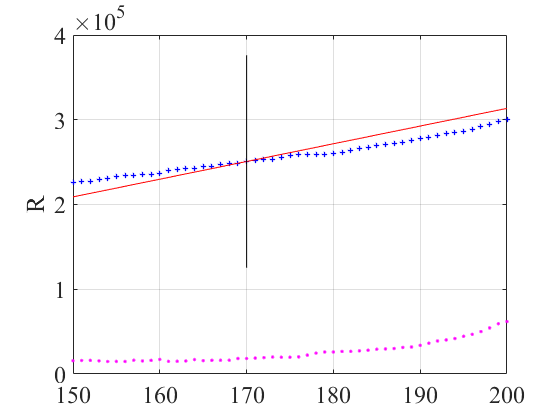


figure(1)
   FS = 18;
   
   H = plot(1:Ndays,Rd,'b+','linewidth',1);
   set(H,'markersize',4,'markerfacecolor','b')
   hold on
   plot(t,y,'r')
   plot([T,T],[0.5*Rd(T), 1.5*Rd(T)],'k')
   
   xlim([tMin tMax])
%   set(gca,'xtick',0:50:tMax)
   grid on; box on;
   ylabel('R')
   set(gca,'fontsize',FS)
   set(gca,'fontName','times')
   
   plot(1:Ndays,Id,'m.')

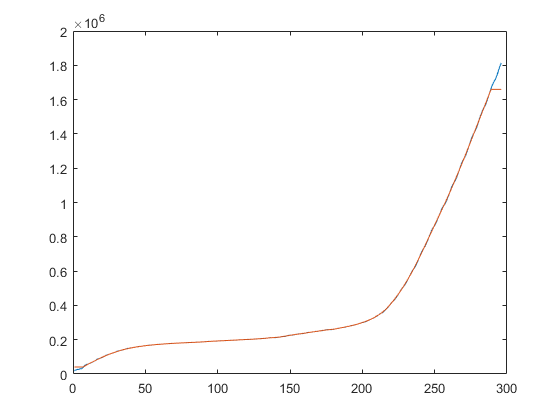

   
 % b = 0.04;
% 
%  m =1120; 
%  T = 75;
% 
%  yB = Id(T) - m.*T ;
% 
% xt = 1:300;
% y = m.*xt + yB;
% 
% zz = (m/Id(T))/b+1

% ====================================================================
Ra = Rd; Ia = Id;


for c = 4:Ndays-3
     Ra(c) = sum(Rd(c-3:c+3))./7;
     Ia(c) = sum(Id(c-3:c+3))./7;
end
Ra(1:6) = Ra(7); 
Ra(Ndays-6:Ndays) = Ra(Ndays-7);
Ia(1:6) = Ia(7); 
Ia(Ndays-6:Ndays) = Ia(Ndays-7);

figure(2)
plot(1:Ndays,Rd)
hold on
plot(1:Ndays,Ra)

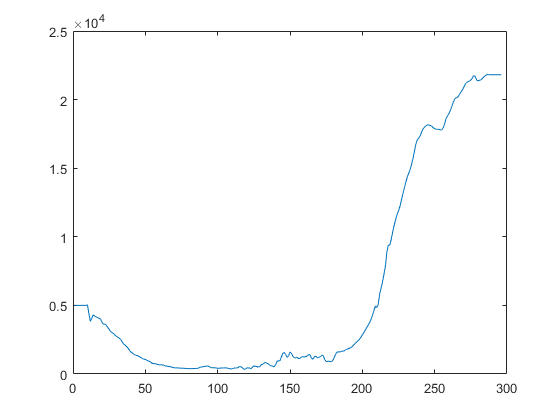


figure(3)
%dRadt = gradient(Ra(5:Ndays-5));
dRadt = gradient(Ra,1);
dRadt(1:8) = dRadt(9);
dRadt(Ndays-8:Ndays) = dRadt(Ndays-9);
plot(1:Ndays,dRadt)

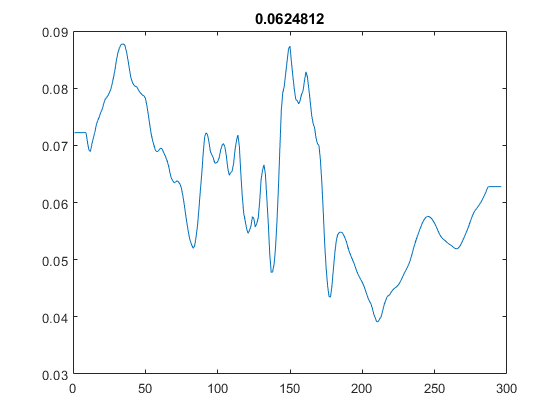


figure(4)
Bd = dRadt./Ia;

for c = 4:Ndays-3
     Bd(c) = sum(Bd(c-3:c+3))./7;
     
end
Bd(1:8) = Bd(9); 
Bd(Ndays-8:Ndays) = Bd(Ndays-9);

plot(1:Ndays,Bd)
title(mean(Bd))